clear
close all

## Исходные данные

Координаты базовой станции

kama_card = [29, 17, 11];

Данные базовой станции:

*Азимут*:    $1°=180\cdot 2^{-14} \cdot \textrm{code}$;    диапазон от 0.0° до 359.9890°

*Места*:     $1°=180\cdot 2^{-14} \cdot \textrm{code}$;    диапазон от −11.2390° до 89.9890°

*Дальность:*    $1\;\mathrm{м}=\textrm{code}$;    диапазон от 100 м до 8_388_607 м

Тестовый массив генерируется с помощью ГСВ с равномерным распределением:

buf_len = 1e7;

az_max = 2^15 - 1;
el_max = 2^13 - 1;
r_max = 2^23 - 1;

az_min = 0;
el_min = -2^10 - 1;
r_min = 100;

in_code = [az_max - az_min, el_max - el_min, r_max - r_min] .* rand(buf_len,3) + [az_min, el_min, r_min];
in_code = round(in_code, 0);

Получение сферических и декактовых координат из кода коодинат 

in_sph = code2deg(in_code);
in_card = sphdeg2card(in_sph);

Удаление данных, которые удолетворяют условию (далеких от реальности):

$z>100\;\textrm{км}$    и     $x^2 +y^2 <{100}^2$

ind_del = in_card(:,3) > 1e6 | (in_card(:,1).^2 + in_card(:,2).^2 < 100^2);
in_card(ind_del,:) = [];
in_sph(ind_del,:) = [];
in_code(ind_del,:) = [];
clear ind_del

## Расчет

кода выходных координат с учетом паралакса и его преобразование в сферические и декатовы координаты

out_ref = zeros(length(in_code),3);
[out_ref(:,1), out_ref(:,2), out_ref(:,3)] =...
    ParalaxCalcRef(in_code(:,1), in_code(:,2), in_code(:,3));
out_sph = code2deg(out_ref);
out_card = sphdeg2card(out_sph);

Нахождение разницы входных и выходных  координат

delta_sph = abs(in_sph - out_sph);
delta_sph((delta_sph(:,1) > 180),1) =...
    360 - delta_sph((delta_sph(:,1) > 180),1);
delta_card = abs(in_card - out_card);

Формирование таблицы с результатами

result = table(...
    in_sph(:,1),in_sph(:,2),in_sph(:,3),...
    in_card(:,1),in_card(:,2),in_card(:,3),...
    out_sph(:,1),out_sph(:,2),out_sph(:,3),...
    out_card(:,1),out_card(:,2),out_card(:,3),...
    delta_sph(:,1),delta_sph(:,2), delta_sph(:,3),...
    delta_card(:,1),delta_card(:,2), delta_card(:,3));
result.Properties.VariableNames = {...
    'in_az', 'in_el', 'in_r',...
    'in_x', 'in_y', 'in_z',...
    'out_az', 'out_el', 'out_r',...
    'out_x', 'out_y', 'out_z',...
    'delta_az', 'delta_el', 'delta_r',...
    'delta_x', 'delta_y', 'delta_z'};
clear in_sph in_card out_sph out_card delta_card delta_sph

## Анализ результатов

Построение поля ошибок азимута больших 0.1

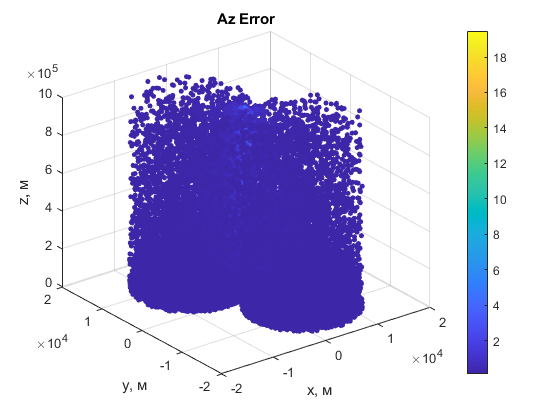

figure("Name","Az_Error")
az_error = table(result.out_x, result.out_y, result.out_z, result.delta_az);
az_error.Properties.VariableNames = {...
    'x', 'y', 'z',...
    'delta'};
az_error(az_error.delta < 0.1,:) = [];

scatter3(az_error.x, az_error.y, az_error.z,...
    10, az_error.delta, 'MarkerFaceColor',"flat");
title("Az Error");
xlabel("x, м"); ylabel("y, м"); zlabel("z, м");
text(0,0,0,"mrl");
text(kama_card(1), kama_card(2), kama_card(3), "kama");
colorbar

% view([90 -90])

Построение поля ошибок места больших 0.1

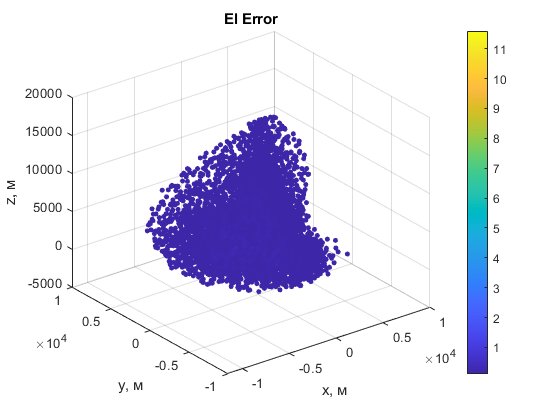

figure("Name","El_Error");
el_error = table(result.out_x, result.out_y, result.out_z, result.delta_el);
el_error.Properties.VariableNames = {...
    'x', 'y', 'z',...
    'delta'};
el_error(el_error.delta < 0.1,:) = [];

scatter3(el_error.x, el_error.y, el_error.z,...
    10, el_error.delta, 'MarkerFaceColor',"flat");
title("El Error");
xlabel("x, м"); ylabel("y, м"); zlabel("z, м");
text(0,0,0,"mrl");
text(kama_card(1), kama_card(2), kama_card(3), "kama");
colorbar;

% view([90 -90]);

Построение зависимости ошибки для азимута и места от расстояния

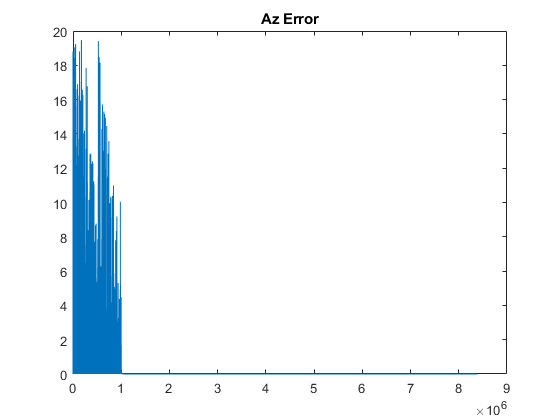

temp = sortrows(result,'in_r','ascend');
figure('Name', "Az_delta")
plot(temp.in_r, temp.delta_az);
title("Az Error");

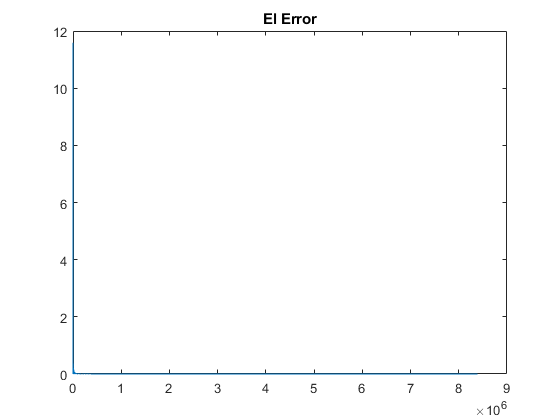

figure('Name', "At_delta")
plot(temp.in_r, temp.delta_el);
title("El Error");

clear temp